# Magnetic Fields and Currents

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Magnetic fields and electric currents show up everywhere from how a compass points north to how an MRI scanner works. In this script, we’ll play around with visualizing and computing the magnetic fields

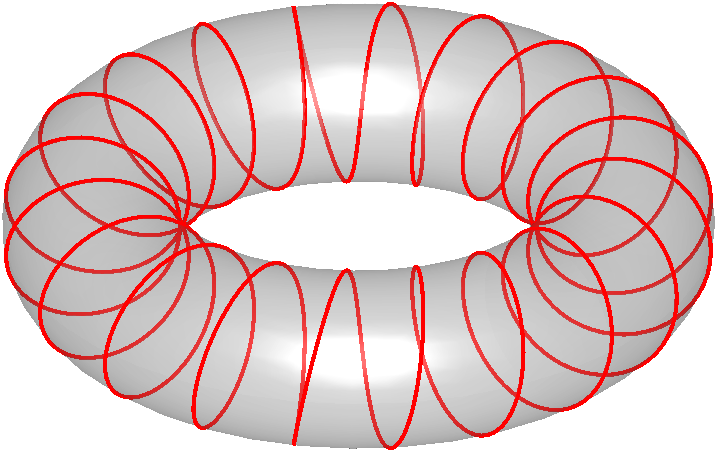

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Magnetic Force on a Charged Particle

When an electric current flows through a wire, it creates a magnetic field around it. That magnetic field can push on other moving charges, whether they’re inside another wire or just drifting through space. This idea that a moving charged particle feels a force in a magnetic field—is one of the core building blocks of electromagnetism.

A charged particle with charge $q$ moving with velocity $\vec{v}$ in a magnetic field $\vec{B}$ experiences a **magnetic (Lorentz) force** given by:


$$\vec{F} = q\, (\vec{v} \times \vec{B}) \qquad (1)$$


Where:

- $\vec{F}$ is the **magnetic force vector** (in **newtons**),

- $q$ is the **electric charge** of the particle (in **coulombs**),

- $\vec{v}$ is the **velocity vector** of the particle (in **meters per second**),

- $\vec{B}$ is the **magnetic flux** density (in **teslas**),

- $\times$ denotes the vector cross product.

  **Try.** Use the control below to simulate the trajectory of a charge particle inside a magnetic field. You can modify the initial velocity direction and magnetic field direction to see how it affects the trajectory.

% Simulation Parameters
v0 = [1; 0.5; 0.3]; % Initial velocity (m/s)
if norm(v0)~=0
    v0 = v0/norm(v0)*1e6;
end

% Magnetic field (Tesla)
B = [0; 0; 1];          % Uniform field in z-direction
 

SimulateChargedParticleInMagneticField(B=B,v0=v0)

function SimulateChargedParticleInMagneticField(opts)
arguments
    opts.v0 (3,1) double                    % Initial velocity (m/s)
    opts.B (3,1) double                     % Magnetic field vector (T)
    opts.q (1,1) double = 1.602e-19        % Charge (C) - electron charge
    opts.m (1,1) double = 1.673e-27        % Mass (kg) - proton mass
    opts.r0 (3,1) double = [0;0;0]         % Initial position (m)
    opts.ShowEnergy (1,1) logical = false  % Display kinetic energy plot
end
    
    % Extract parameters
    InitialVelocity = opts.v0;
    MagneticField = opts.B;
    Charge = opts.q;
    Mass = opts.m;
    InitialPosition = opts.r0; 
    ShowEnergy = opts.ShowEnergy;

    % Time parameters
    FinalTime = 1e-7;
    NumSteps = 100;
    TimeVector = linspace(0, FinalTime, NumSteps);

    % Solve Lorentz force equation: F = q(v × B)
    InitialState = [InitialPosition; InitialVelocity];
    LorentzForce = @(t,y) Charge * cross(y(4:end), MagneticField);
    StateDerivative = @(t,y) [y(4); y(5); y(6); LorentzForce(t,y)/Mass];
    [TimeVector, State] = ode45(StateDerivative, TimeVector, InitialState);
    
    Position = State(:,1:3)';
    Velocity = State(:,4:6)';
    
    % Compute normalized kinetic energy
    if sum(Velocity(:,1)) ~= 0
        KineticEnergy = sum(Velocity.^2) / norm(Velocity(:,1).^2);
    else
        KineticEnergy = zeros(1, NumSteps);
    end
    
    % Setup figure
    figure(Position=[0 0 840 500])
    if ShowEnergy
        Layout = tiledlayout(1, 2);
        nexttile
    end

    hold on
    grid on
    box on
    view(-45, 30)
    xlabel("X Position (m)");
    ylabel("Y Position (m)");
    zlabel("Z Position (m)");
    
    % Calculate axis limits with margin
    XRange = [min(Position(1,:)) max(Position(1,:))];
    YRange = [min(Position(2,:)) max(Position(2,:))];
    ZRange = [min(Position(3,:)) max(Position(3,:))];
    MaxRange = max([diff(XRange) diff(YRange) diff(ZRange) 1e-6]);
    Margin = 0.1;
    
    XLimits = XRange + [-1 1] * Margin * MaxRange;
    YLimits = YRange + [-1 1] * Margin * MaxRange;
    ZLimits = ZRange + [-1 1] * Margin * MaxRange;
    xlim(XLimits);
    ylim(YLimits);
    zlim(ZLimits);

    % Draw magnetic field vectors
    [GridX, GridY] = meshgrid(linspace(XLimits(1)+0.05*MaxRange, XLimits(2)-0.05*MaxRange, 5), ...
                              linspace(YLimits(1)+0.05*MaxRange, YLimits(2)-0.05*MaxRange, 5));
    GridZ = zeros(size(GridX)) + mean(ZLimits);

    FieldScale = diff(ZLimits) * 0.1;
    FieldU = ones(size(GridX)) * MagneticField(1) * FieldScale;
    FieldV = ones(size(GridX)) * MagneticField(2) * FieldScale;
    FieldW = ones(size(GridX)) * MagneticField(3) * FieldScale;
    FieldQuiver = quiver3(GridX, GridY, GridZ, FieldU, FieldV, FieldW, ...
                          "off", "filled", SeriesIndex=1, LineWidth=2);

    % Initialize animated elements
    TrajectoryLine = plot3(Position(1,1), Position(2,1), Position(3,1), ...
                           LineStyle="-", LineWidth=2, SeriesIndex=2);
    ParticleMarker = plot3(Position(1,1), Position(2,1), Position(3,1), ...
                           "ro", MarkerSize=12, MarkerFaceColor="r");

    % Add velocity vector
    VelocityScale = diff(XRange) * 0.1 / norm(InitialVelocity);
    VelocityArrow = quiver3(Position(1,1), Position(2,1), Position(3,1), ...
                            InitialVelocity(1)*VelocityScale, ...
                            InitialVelocity(2)*VelocityScale, ...
                            InitialVelocity(3)*VelocityScale, ...
                            "off", "filled", SeriesIndex=5, LineWidth=2, MaxHeadSize=100);
    
    % Add legend and title
    if ShowEnergy
        title(Layout, "Charged Particle Motion in Magnetic Field");
        legend([FieldQuiver, TrajectoryLine, ParticleMarker], ...
               "Magnetic Field", "Trajectory", "Particle", Location="southoutside");
    else
        title("Charged Particle Motion in Magnetic Field");
        legend([FieldQuiver, TrajectoryLine, ParticleMarker], ...
               "Magnetic Field", "Trajectory", "Particle", Location="bestoutside");
    end
    
    hold off
    
    % Setup energy plot if requested
    if ShowEnergy
        nexttile
        EnergyPlot = plot(TimeVector(1), KineticEnergy(1));
        xlim([min(TimeVector), max(TimeVector)])
        ylim([0 2])
        xlabel("Time (s)")
        ylabel("Kinetic Energy (normalized)")
        yticks(0)
    end

    % Animation loop
    for i = 2:NumSteps
        set(TrajectoryLine, "XData", Position(1,1:i), ...
                            "YData", Position(2,1:i), ...
                            "ZData", Position(3,1:i));

        set(ParticleMarker, "XData", Position(1,i), ...
                            "YData", Position(2,i), ...
                            "ZData", Position(3,i));

        set(VelocityArrow, "XData", Position(1,i), ...
                           "YData", Position(2,i), ...
                           "ZData", Position(3,i), ...
                           "UData", Velocity(1,i)*VelocityScale, ...
                           "VData", Velocity(2,i)*VelocityScale, ...
                           "WData", Velocity(3,i)*VelocityScale);
        
        if ShowEnergy
            set(EnergyPlot, "XData", TimeVector(1:i), ...
                            "YData", KineticEnergy(1:i));
        end
        
        drawnow;
    end
end

 **Exercise 1.** Using the visualization above, answer the following question.

a. What happens if a particle's velocity is null (zero) in a magnetic field? 

CheckExercise1a("B")

Correct! The magnetic component of the Lorentz force is given by ( \vec{F} = q\vec{v} \times \vec{B} ). If ( \vec{v} = 0 ), then ( \vec{F} = 0 ).


function CheckExercise1a(Answer)
    switch (Answer)
        case "A"
            warning("Incorrect. The Lorentz force depends on the velocity of the particle. If the velocity is zero, the force is also zero.")
        case "B"
            disp("Correct! The magnetic component of the Lorentz force is given by ( \vec{F} = q\vec{v} \times \vec{B} ). If ( \vec{v} = 0 ), then ( \vec{F} = 0 ).")
        case "C"
            warning("Incorrect. The particle cannot move in a circular path if it is not moving at all.")
        case "D"
            warning("Incorrect. With zero velocity, there is no magnetic force to cause any acceleration.")
        otherwise
            warning("Please select a valid answer.")
    end
end

b. What happens if a particle's velocity is parallel to the magnetic field?

CheckExercise1b("B")

Correct! The cross product ( \vec{v} \times \vec{B} ) is zero when ( \vec{v} ) is parallel to ( \vec{B} ), so the force is zero.


function CheckExercise1b(Answer)
    switch (Answer)
        case "A"
            warning("Incorrect. The force is maximum when the velocity is perpendicular to the magnetic field, not parallel.");
        case "B"
            disp("Correct! The cross product ( \vec{v} \times \vec{B} ) is zero when ( \vec{v} ) is parallel to ( \vec{B} ), so the force is zero.");
        case "C"
            warning("Incorrect. A helical path occurs when the velocity has both parallel and perpendicular components relative to the magnetic field.");
        case "D"
            warning("Incorrect. The magnetic force does not reverse the direction of a particle moving parallel to the field; it simply does not act on it.");
        otherwise
            warning("Please select a valid answer.");
    end
end

c. What happens if a particle's velocity is perpendicular to the magnetic field?

CheckExercise1c("C")

Correct! The magnetic force acts perpendicular to the velocity, resulting in uniform circular motion.


function CheckExercise1c(Answer)
    switch (Answer)
        case "A"
            warning("Incorrect. The magnetic force acts as a centripetal force, causing the particle to move in a circular path.")
        case "B"
            warning("Incorrect. The force is actually at its maximum when the velocity is perpendicular to the magnetic field.")
        case "C"
            disp("Correct! The magnetic force acts perpendicular to the velocity, resulting in uniform circular motion.")
        case "D"
            warning("Incorrect. The magnetic force does not perform work and cannot stop the particle; it only changes the direction of motion.")
        otherwise
            warning("Please select a valid answer.")
    end
end

## **Work Done by the Magnetic Force**

In the previous section, we studied how the trajectory of a charged particle is changed while experiencing the force from a magnetic field. We should now look at how much energy is transmitted, or in other words how much work is done by the magnetic force on the charged particle.

We know that the magnetic force is given by:


$$\vec{F} = q\, (\vec{v} \times \vec{B}) \qquad (1)$$


If work is defined as:


$$W = \int \vec{F}\cdot d\vec{r} = \int \vec{F}\cdot\vec{v}dt\qquad (2)$$


 **Exercise 2.** After replacing $\vec{F}$ in $(2)$ by its expression from $(1)$, what can you tell about the work $W$ done by the magnetic force on the particle?

- 
$$W = \int q (\vec{v} \times \vec{B}) \cdot \vec{v} dt$$


- 
$$W = 0$$


- 
$$W = \int q (\vec{B} \times \vec{v}) \cdot \vec{v} dt$$


- 
$$W = \int q (\vec{v} \times \vec{v}) \cdot \vec{B} dt$$


CheckExercise2(2)

Correct! Magnetic forces do no work!


function CheckExercise2(Answer)
    switch (Answer)
        case 1
            warning("Your calculations are correct so far, but you can go a step further using the following identity: (a×b)·a = 0.")
            displayFormula()
        case 2
            disp("Correct! Magnetic forces do no work!")
        case 3
            warning("Your calculations are correct so far, but you can rearrange the dot product to get closer to the answer: (a×b)·c = (c×a)·b.")
        case 4
            warning("Your calculations are correct so far, but you can go a step further using the identity: a×a = 0.")
        otherwise
            warning("Please select a valid answer.")
    end
end

Let's take a step back and look back at our particle simulation from earlier. The magnetic force was clearly having an effect on the trajectory of the particle, so how much work was provided to the particle?

 **Demonstration.** Re-run the simulation, only this time we will also look at the effect on the kinetic energy of the particle, if work is applied to the particle, the kinetic energy should go up.

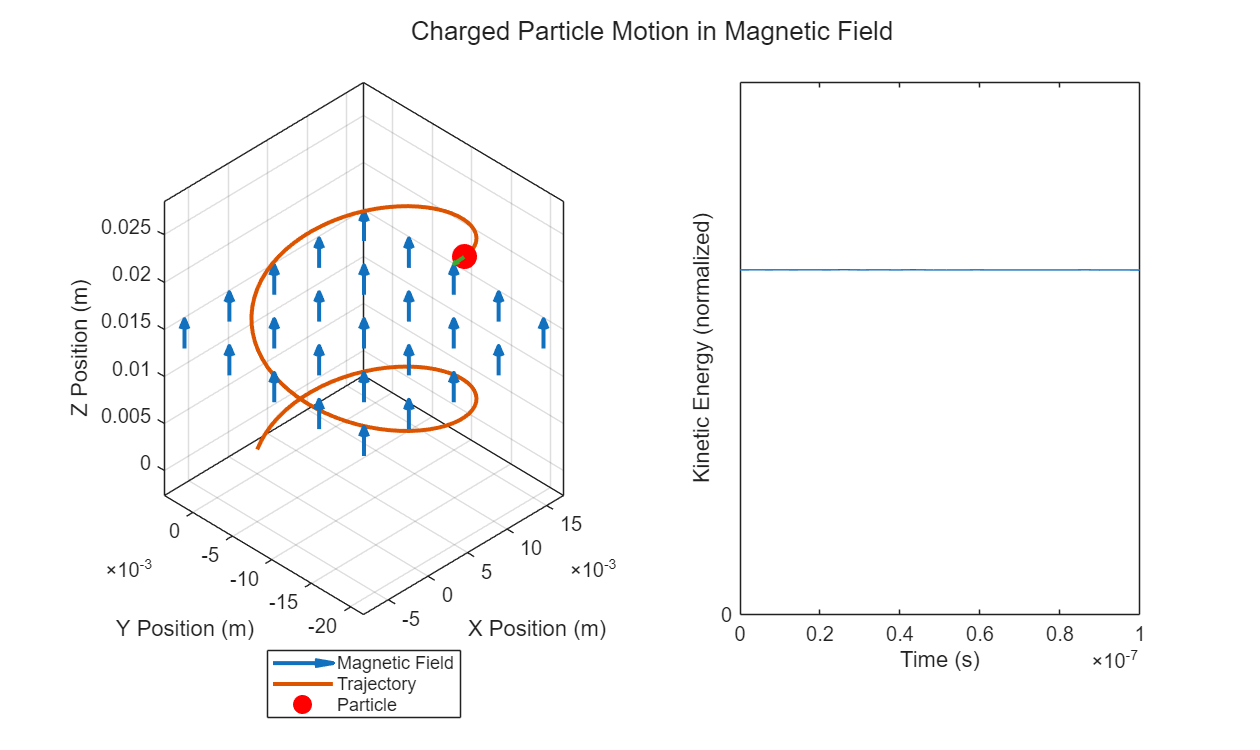

% Simulation Parameters
v0 = [1; 0.5; 0.3]; % Initial velocity (m/s)
if norm(v0)~=0
    v0 = v0/norm(v0)*1e6;
end

% Magnetic field (Tesla)
B = [0; 0; 1];          % Uniform field in z-direction
 

SimulateChargedParticleInMagneticField(B=B,v0=v0,ShowEnergy=true)

## Magnetic Fields Due to Electric Current 

In the previous sections, we have focused on the magnetic force experienced by a charged particle in a magnetic field, but we have not yet explored what a magnetic field actually is or where it comes from. One of the fundamental sources of a magnetic field is an **electric current**, which is the flow of electric charge through a conductor. 

An **electric current** is the flow of electric charge through a conductor, such as a wire. In most cases, this flow is due to the movement of electrons. The current is a measure of how much charge passes through a given point in the conductor per unit of time, and it is usually denoted by the symbol $i$ or $I$. Its SI unit is the **ampere (A)**, where 1 A = 1 coulomb of charge passing per second.

 **Exercise 3.** Use the button below to generate a problem statement and solve the problem. You can use the edit field below to enter your answer or even type your mathematical formula (use $q$ for charge and $tau$ for the time scale).

Prob = GenerateProblemStatement3; 

$$\mathrm{A copper wire carries a flow of electrons such that}q=8\mathrm{coulombs of charge pass through a cross‑section of the wire every}\tau =5\mathrm{seconds.}$$

$$\mathrm{What is the current in the wire?}$$


function y = GenerateProblemStatement3()
Charge = 1:10;
Charge = Charge(randi(10));
TimeScale = randi([1 5]);

displayFormula(['"A copper wire carries a flow of electrons such that "' ...
    "q == Charge" ...
    '" coulombs of charge pass through a cross‑section of the wire every "' ...
    "tau == TimeScale" ...
    '" seconds."' ])

displayFormula('"What is the current in the wire?"')

y.ID = "Ex3";
y.Charge = Charge;
y.TimeScale = TimeScale;
end

 
displayFormula('"Hint: Check the dimensions: q has units of coulombs, and \\tau has units of seconds. How do these combine to produce amperes?"')

$$\mathrm{Hint: Check the dimensions: q has units of coulombs, and \backslash tau has units of seconds. How do these combine to produce amperes?}$$

CheckExercise3(Prob,"q/tau" )

Good job! You computed the current correctly.



function CheckExercise3(Prob,Answer)
% Check that it is the right exercise
if ~contains(Prob.ID,"Ex3")
    warning("Click generate problem above to generate a problem statement.")
    return
end

% Check Answer
Answer = replace(Answer,"q",string(Prob.Charge));
Answer = replace(Answer,"tau",string(Prob.TimeScale));
Answer = double(str2sym(Answer));
RightAnswer = Prob.Charge/Prob.TimeScale;
if IsClose(Answer,1/RightAnswer)
    warning("You are close, check the unit of your calculation, they should be in Coulomb per second (C/s)")
    return
end
if IsClose(Answer,RightAnswer)
    disp("Good job! You computed the current correctly.")
else
    warning("Incorrect. Please try again (consider using the hint above).")
end
end

### The Biot-Savart Law

Now that we know magnetic fields are produced by moving charges, we need a way to calculate the magnetic field created by a given current. The **Biot–Savart Law** provides this connection between electric currents and the magnetic fields they generate:


$$\vec{B}(\vec{r}) = \frac{\mu_0}{4\pi} \int{ \frac{I\vec{d\mathcal{l}} \times \hat{r}}{r^2} } \qquad (3)
$$


**Where:**

- $\vec{B}(\vec{r})$ is the **magnetic field vector** at the position $\vec{r}$ (in **teslas**, T),

- $\mu_0$ is the **permeability of free space**, equal to $4\pi \times 10^{-7}\$ (in **teslas meter per amperes, **$\text{T\cdot m/A}$),

- $I$ is the **electric current** flowing through the conductor (in **amperes**, A),

- $d\vec{\mathcal{l}}$ is an **infinitesimal vector element** of the current-carrying wire, pointing in the direction of current flow (in **meters**, m),

- $\hat{r}$ is a **unit vector** pointing from the current element toward the point where $\vec{B}$ is being evaluated (dimensionless),

- $r$ is the **distance** between the current element and the observation point (in **meters**, m),

- $\times$ denotes the **vector cross product**, indicating that the direction of $\vec{B}$ is perpendicular to both $d\vec{\mathcal{l}}$ and $\hat{r}$.

### Example: Magnetic Field of a Current Loop

In this example, we will work step by step to compute the magnetic field generated by a current loop at one point in space.

  **Try.** Click the button to generate a circular current loop and visualize its magnetic field.

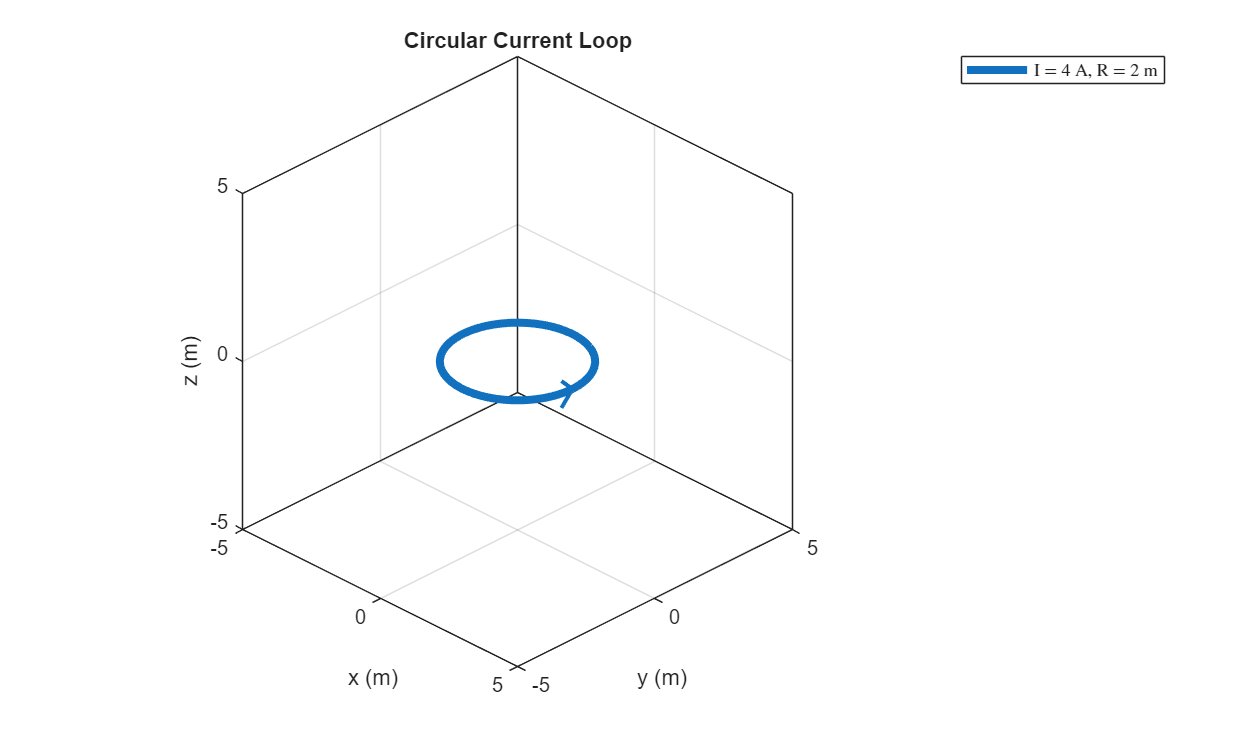

 
CurrentLoop = GenerateCurrentLoop;
CurrentLoop = PlotCurrentLoop(CurrentLoop);


function ProblemData = GenerateCurrentLoop(varargin)

% Initialize problem data structure
if nargin == 0
    ProblemData.ID = "CurrentLoop";
    ProblemData.Current = randi(5);
    ProblemData.CurrentSegment = 1;
    ProblemData.NumSegment = 5;
    ProblemData.QueryPoint = [0 0 0];
    ProblemData.MagneticField = [0 0 0];
    ProblemData.AxesHandle = [];
    return
else
    ProblemData = varargin{1};
    for ii = 2:2:size(varargin,2)
        ProblemData.(varargin{ii}) = varargin{ii+1};
    end
end

end

function ProblemData = PlotCurrentLoop(ProblemData,opts)
arguments
    ProblemData (1,1) struct
    opts.HighlightSegment (1,1) logical = false;
    opts.ShowDistanceVec (1,1) logical = false;
    opts.ShowQueryPoint (1,1) logical = false;
    opts.ShowTotalField (1,1) logical = false
    opts.ShowdB (1,1) logical = false
end
    
    % Check that we have the right problem data
    if ProblemData.ID ~= "CurrentLoop"
        disp("Generate a current loop problem before to run this.")
        return
    end

    % Check if figure needs to be created
    if isempty(ProblemData.AxesHandle)
        figure(Position=[0 0 840 500]);
        ProblemData.AxesHandle = axes;
        axis(ProblemData.AxesHandle,"equal")
        xlim(ProblemData.AxesHandle,[-5 5])
        ylim(ProblemData.AxesHandle,[-5 5])
        zlim(ProblemData.AxesHandle,[-5 5])
        xlabel(ProblemData.AxesHandle,"x (m)")
        ylabel(ProblemData.AxesHandle,"y (m)")
        zlabel(ProblemData.AxesHandle,"z (m)")
        view(ProblemData.AxesHandle,45,30)
        title(ProblemData.AxesHandle,'Circular Current Loop')
        grid(ProblemData.AxesHandle,"on")
        box(ProblemData.AxesHandle,"on")
    end



    % Define circular loop geometry
    NumPoints = lcm(60,ProblemData.NumSegment);
    CompleteLoopAngle = linspace(0, 2*pi, NumPoints);  % Angular positions around the loop (radians)
    PointPerSegment = NumPoints/ProblemData.NumSegment;
    CompleteLoopAngle = circshift(CompleteLoopAngle,(ProblemData.CurrentSegment-1)*PointPerSegment);
    SegmentAngle = CompleteLoopAngle(1:PointPerSegment);
    LoopAngle = CompleteLoopAngle([PointPerSegment:end 1]);
    LoopRadius = 2;  % Radius of the current loop (meters)
    
    % Calculate Cartesian coordinates of the loop
    SegmentX = LoopRadius * cos(SegmentAngle);
    SegmentY = LoopRadius * sin(SegmentAngle);
    SegmentZ = 0 * SegmentAngle;
    LoopX = LoopRadius * cos(LoopAngle);
    LoopY= LoopRadius * sin(LoopAngle);
    LoopZ= 0 * LoopAngle;  % Loop lies in the xy-plane
    
    % ---- Start Plotting -------------------------------------------
    hold(ProblemData.AxesHandle,"on")

    % ---- Current Loop
    delete(findobj('Tag','Loop','Parent',ProblemData.AxesHandle));
    LoopPlotHandle = plot3(ProblemData.AxesHandle,...
        LoopX, LoopY, LoopZ, ...
        LineWidth=4, ...
        DisplayName="I = " + ProblemData.Current + " A, R = 2 m", ...
        SeriesIndex=1, ...
        Tag="Loop");
    ForLegend = LoopPlotHandle;

    % ---- Plot Current Direction
    delete(findobj('Tag','CurrentDir','Parent',ProblemData.AxesHandle));
    DirX = [LoopRadius LoopRadius LoopRadius];
    DirY = [-0.4 0 -0.4];
    DirZ = [-0.4 0 0.4];
    plot3(ProblemData.AxesHandle,...
        DirX, DirY, DirZ, ...
        LineWidth=2, ...
        SeriesIndex=1,...
        Tag="CurrentDir");

    % ---- Plot Current Segment
    delete(findobj('Tag','SegmentPlot','Parent',ProblemData.AxesHandle));
    SegmentPlot = plot3(ProblemData.AxesHandle,...
        SegmentX, SegmentY, SegmentZ,...
            LineWidth=4,...
            SeriesIndex=1,...
            Tag="SegmentPlot");
    if opts.HighlightSegment
        SegmentPlot.SeriesIndex = 2;
    end

    % ---- Query Point
    if opts.ShowQueryPoint
        % Set the query point for the magnetic field calculation
        delete(findobj('Tag','QueryPoint','Parent',ProblemData.AxesHandle));
        QueryPointHandle = scatter3(ProblemData.AxesHandle,...
            ProblemData.QueryPoint(1),...
            ProblemData.QueryPoint(2),...
            ProblemData.QueryPoint(3),...
            'filled',...
            SeriesIndex=5,...
            DisplayName="Query Point",...
            Tag="QueryPoint");
        ForLegend = [ForLegend, QueryPointHandle];
    end

    % ---- Distance Vector
    SegmentPosition = [median(SegmentX) median(SegmentY) median(SegmentZ)];
    DistanceVector = ProblemData.QueryPoint - SegmentPosition;
    delete(findobj('Tag','R','Parent',ProblemData.AxesHandle))
    if opts.ShowDistanceVec
        quiver3(ProblemData.AxesHandle,...
            SegmentPosition(1),SegmentPosition(2),SegmentPosition(3),...
            DistanceVector(1),DistanceVector(2),DistanceVector(3),...
            Tag="R",...
            SeriesIndex=6,...
            LineWidth=2,...
            AutoScale="off",...
            DisplayName="$\vec{r}$");
    end

    % ---- Show Infitesimal field
    dl = [SegmentX(end)-SegmentX(1); SegmentY(end)-SegmentY(1); SegmentZ(end)-SegmentZ(1)];
    dB = ProblemData.Current * cross(dl,DistanceVector) / norm(DistanceVector)^2;
    ProblemData.MagneticField = ProblemData.MagneticField + dB;
    delete(findobj('Tag','dB','Parent',ProblemData.AxesHandle))
    if opts.ShowdB
        dBHandle = quiver3(ProblemData.AxesHandle,...
            ProblemData.QueryPoint(1),ProblemData.QueryPoint(2),ProblemData.QueryPoint(3),...
            dB(1),dB(2),dB(3),...
            Tag="dB",...
            SeriesIndex=4,...
            LineWidth=2,...
            AutoScale="off",...
            DisplayName="$dB$");
        ForLegend = [ForLegend, dBHandle];
    end

    % Show total field
    delete(findobj('Tag','B','Parent',ProblemData.AxesHandle))
    if opts.ShowTotalField
        BHandle = quiver3(ProblemData.AxesHandle, ...
            ProblemData.QueryPoint(1),ProblemData.QueryPoint(2),ProblemData.QueryPoint(3),...
            ProblemData.MagneticField(1),ProblemData.MagneticField(2),ProblemData.MagneticField(3),...
            Tag="B",...
            SeriesIndex=7,...
            LineWidth=2,...
            AutoScale="off",...
            DisplayName="$B$");
        ForLegend = [ForLegend, BHandle];
    end

    % Stop Plotting
    hold(ProblemData.AxesHandle,"off")

    % Add Legend
    legend(ForLegend,Location="bestoutside",Interpreter="latex")

end

  **Try.** Enter a point where you would like to compute the field.

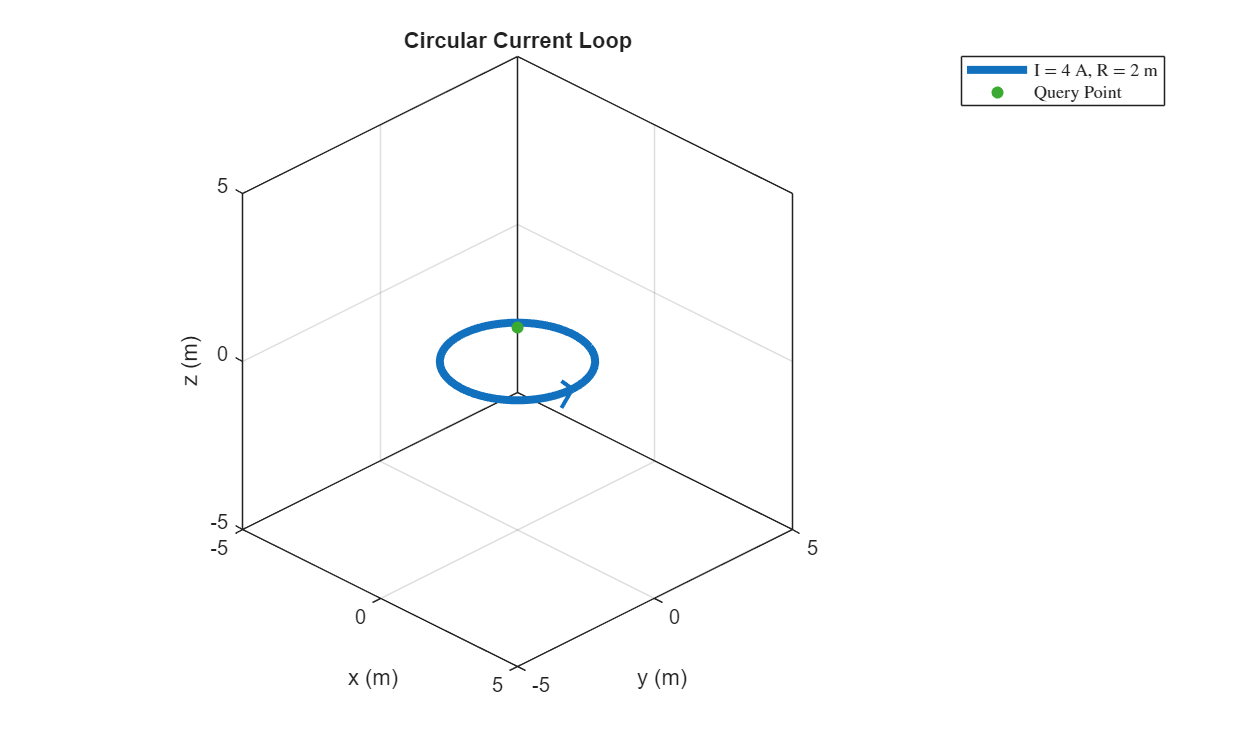

CurrentLoop = GenerateCurrentLoop(CurrentLoop,"QueryPoint",[0,0,1]); 
CurrentLoop = PlotCurrentLoop(CurrentLoop,ShowQueryPoint=true);

To simplify the integral in (3), we approximate its value by dividing the current loop into many small segments and summing their individual contributions.

  **Try.** Use the spinner below to select your number and segment and visualize their size.

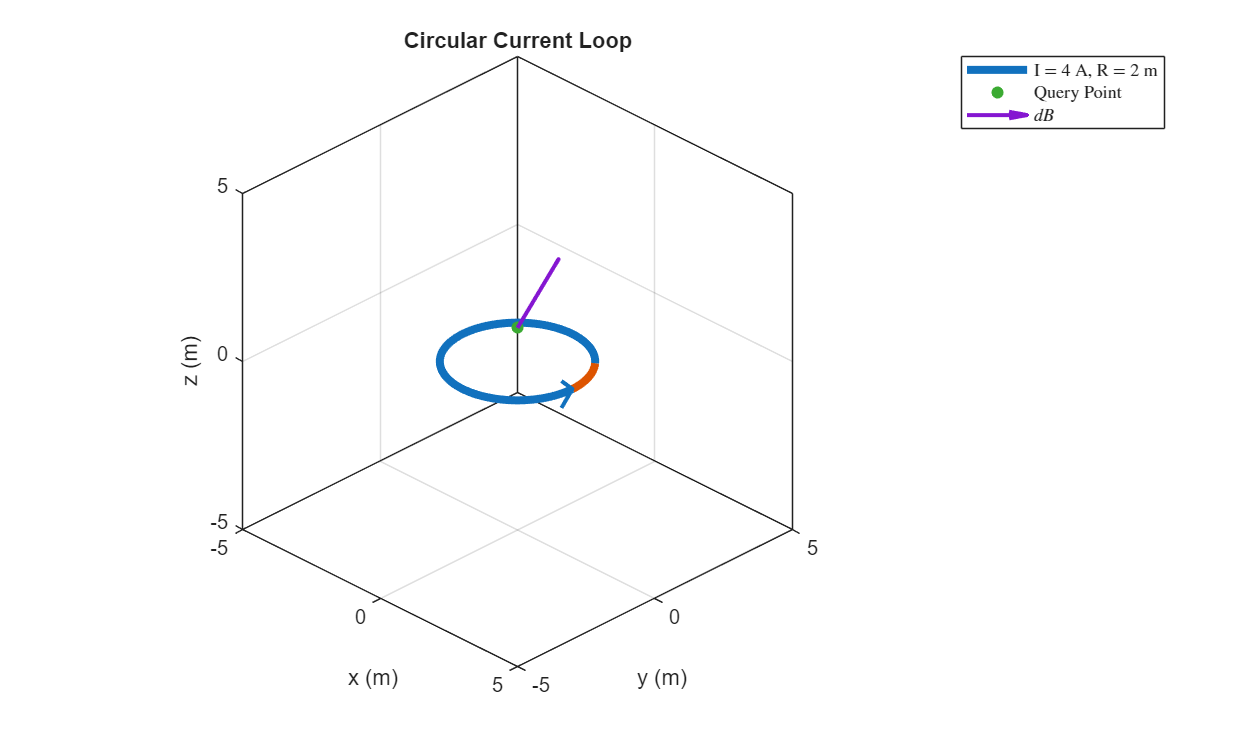

CurrentLoop = GenerateCurrentLoop(CurrentLoop,"MagneticField",[0 0 0]);
NumSegment = 8;
 
CurrentLoop = GenerateCurrentLoop(CurrentLoop,"NumSegment",NumSegment);
CurrentLoop = PlotCurrentLoop(CurrentLoop,ShowQueryPoint=true,ShowdB=true,HighlightSegment=true);


$$\vec{dB}_{seg}(\vec{r}) = \frac{\mu_0}{4\pi} { \frac{I\vec{d\mathcal{l}} \times \hat{r}}{r^2} } \qquad (3)
$$


  **Try.** Run the simulation below to see how the individual field pieces combine to form the total field.

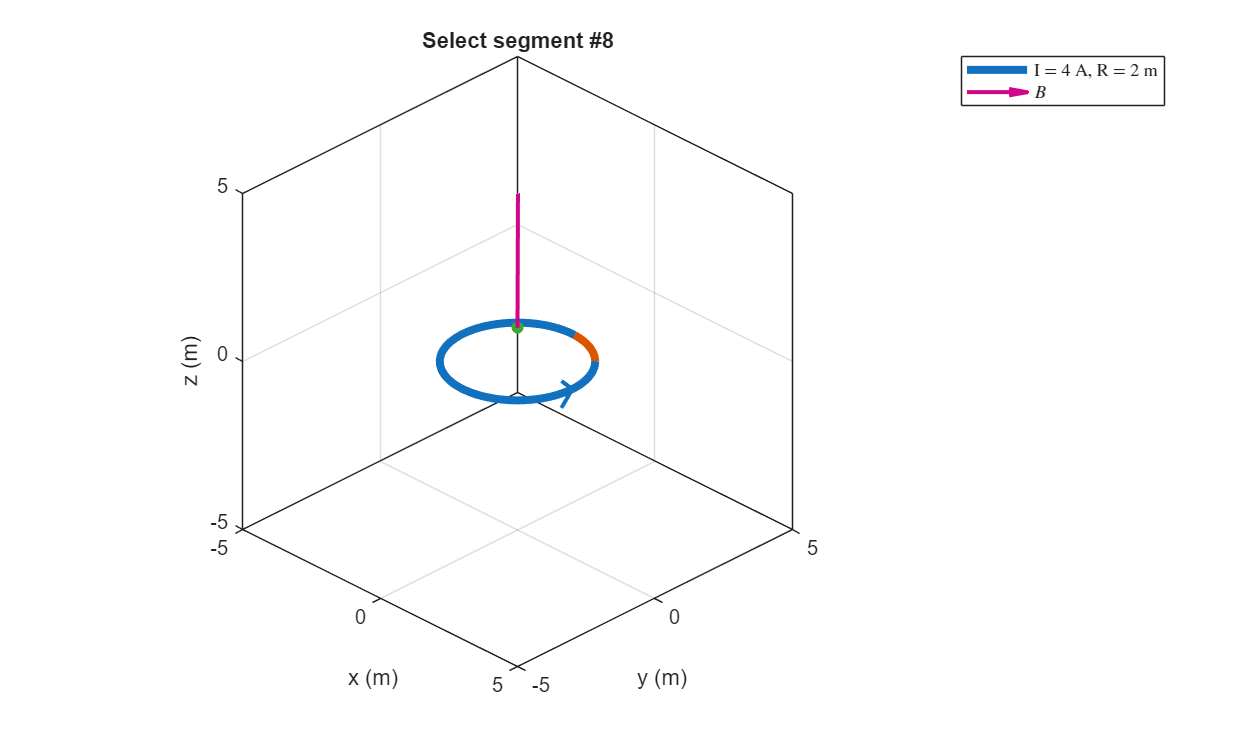

 
CurrentLoop = GenerateCurrentLoop(CurrentLoop,"NumSegment",NumSegment,"CurrentSegment",1);
CurrentLoop = PlotCurrentLoop(CurrentLoop,ShowQueryPoint=true);
CurrentLoop = GenerateCurrentLoop(CurrentLoop,"MagneticField",[0 0 0]);
pause(0.3);
for iSeg = 1:NumSegment
    CurrentLoop = GenerateCurrentLoop(CurrentLoop,"NumSegment",NumSegment,"CurrentSegment",iSeg);
    title(CurrentLoop.AxesHandle,"Select segment #"+iSeg)
    MagneticField = CurrentLoop.MagneticField; % Store magnetic field
    CurrentLoop = PlotCurrentLoop(CurrentLoop,HighlightSegment=true);
    pause(0.3);
    CurrentLoop = PlotCurrentLoop(CurrentLoop,HighlightSegment=true,ShowDistanceVec=true);
    pause(0.3);
    CurrentLoop = PlotCurrentLoop(CurrentLoop,HighlightSegment=true,ShowdB=true);
    pause(0.3);
    CurentLoop.MagneticField = MagneticField; % Reset magnetic field
    CurrentLoop = PlotCurrentLoop(CurrentLoop,HighlightSegment=true,ShowTotalField=true);
    pause(0.3);
end

## Ampère's Circuital Law

Ampère's Circuital Law provides a powerful method for calculating magnetic fields when there is sufficient symmetry. It states that the line integral of the magnetic field around a closed loop equals μ₀ times the current enclosed by the loop:


$$\oint \vec{B} \cdot d\vec{l} = \mu_0 I_{\text{enclosed}} \qquad (5)$$


Before we continue, we should look at how we can use this law to compute the magnetic field in a simple case: an infinitely long wire.

  **Try.** Click the button below to visualize the wire.

PlotAmpereExample(ConfigType="Wire",ShowAmperian=false);  

Because the wire is infinitely long, the field should not depend on the position along the Z axis.

 **Demonstration.** Click the button below to see a step by step explanation on how to use Ampere's law.

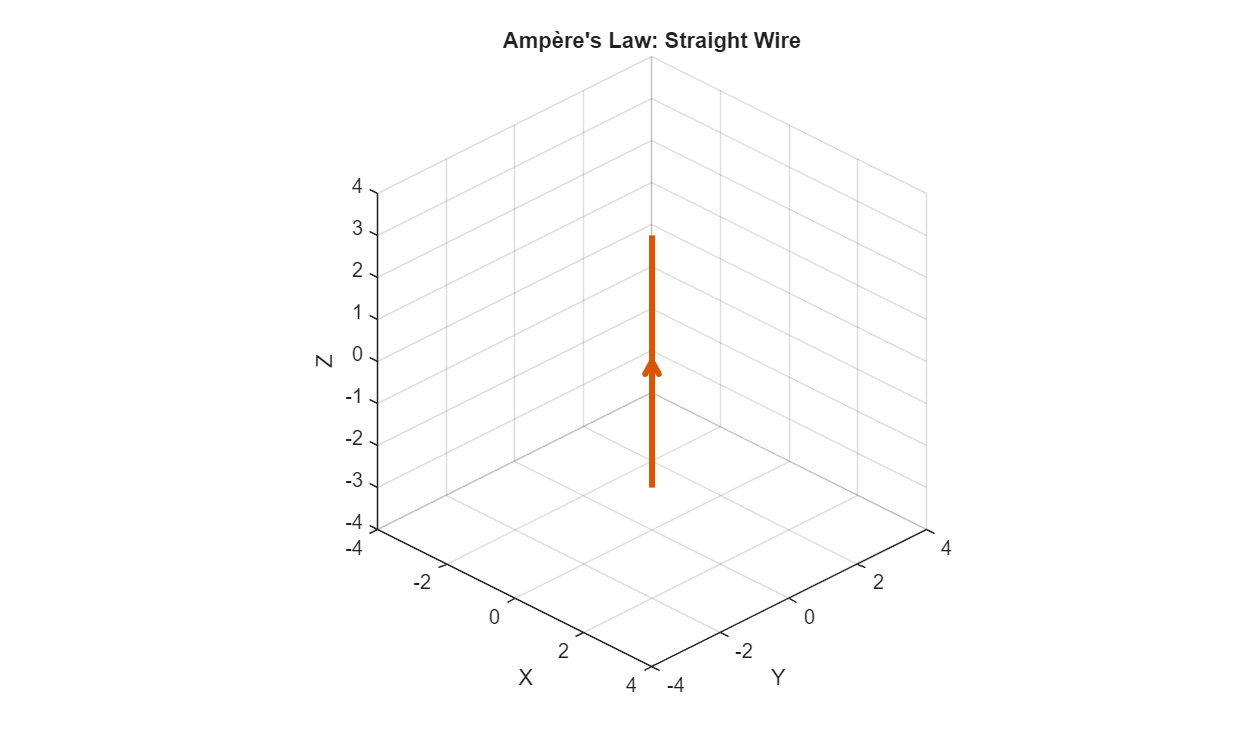

 
% Show setup
handle = PlotAmpereExample(ConfigType="Wire",ShowAmperian=false,WithAnnotation=true);

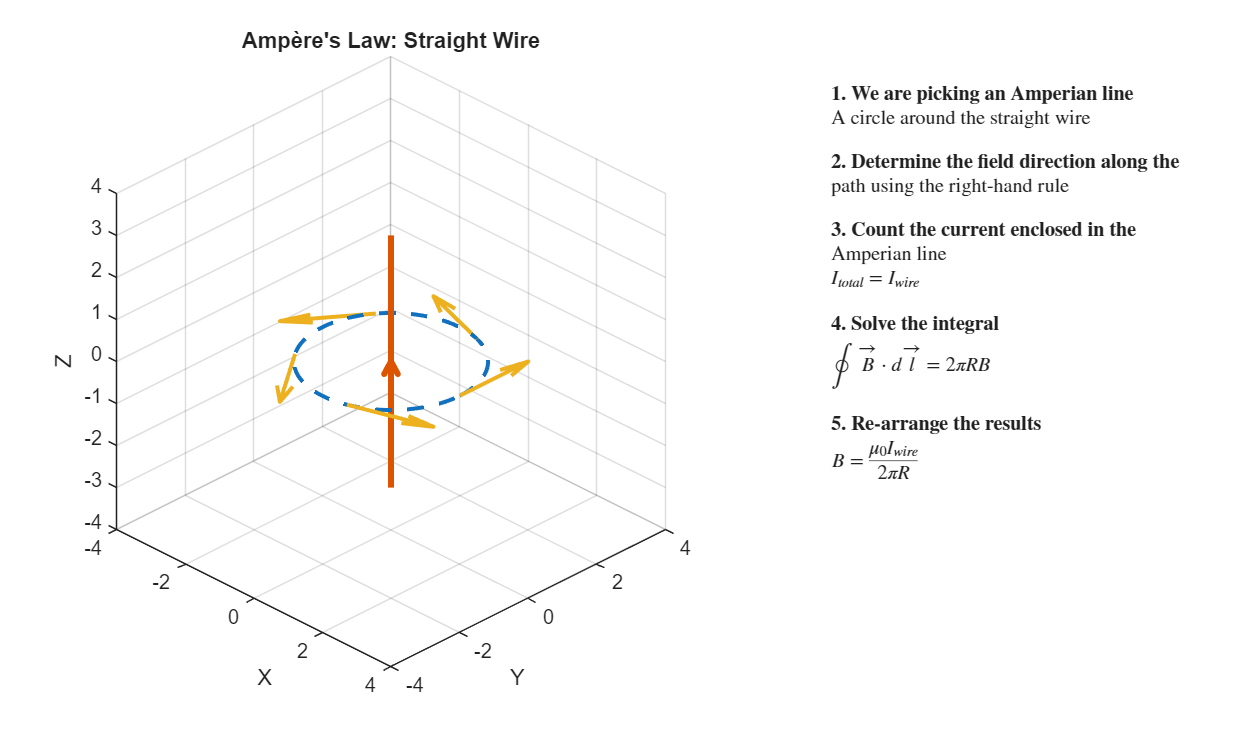

t = annotation(handle,"textbox",Position=[0.65 0.1 0.3 0.8],LineStyle="none",Interpreter="latex");
t.String = "\bf 1. We are picking an Amperian line";
for frame = 1:15
    drawnow
end
pause(2)

% Show Amperian line
t.String = [t.String;...
    "A circle around the straight wire";...
    ""];
handle = PlotAmpereExample(ConfigType="Wire",ShowAmperian=true,Figure=handle);
for frame = 1:15
    drawnow
end
pause(2)

% Show B field
t.String = [t.String;...
    "\bf 2. Determine the field direction along the path using the right-hand rule";...
    ""];
handle = PlotAmpereExample(ConfigType="Wire",ShowAmperian=true,Figure=handle,ShowB=true);
for frame = 1:15
    drawnow
end
pause(2)

% Count the current enclosed in Amperian line
t.String = [t.String;...
    "\bf 3. Count the current enclosed in the Amperian line";...
    "$$I_{total} = I_{wire}$$";
    ""];
handle = PlotAmpereExample(ConfigType="Wire",ShowAmperian=true,Figure=handle,ShowB=true);
for frame = 1:15
    drawnow
end
pause(2)

% Solve the integral
t.String = [t.String;...
    "\bf 4. Solve the integral";...
    "$$\oint \vec{B} \cdot d\vec{l} = 2\pi R B$$";
    ""];
handle = PlotAmpereExample(ConfigType="Wire",ShowAmperian=true,Figure=handle,ShowB=true);
for frame = 1:15
    drawnow
end
pause(2)

% Rearrange the results
t.String = [t.String;...
    "\bf 5. Re-arrange the results";...
    "$$B = \frac{\mu_0 I_{wire}}{2\pi R}$$"];
for frame = 1:15
    drawnow
end
pause(2)

**Tips**. The right‑hand rule gives you the **direction** of that magnetic field when applying Ampère’s law to real situations like straight wires or coils.

- Point the **thumb** of your **right hand** in the direction of the conventional current $I$

- Your **fingers curl** naturally around the wire or current‑carrying conductor.

function handle = PlotAmpereExample(opts)
arguments
    opts.ConfigType (1,1) string {mustBeMember(opts.ConfigType,["Wire","Solenoid","Toroid"])}
    opts.ShowAmperian (1,1) logical = false;
    opts.ShowB (1,1) logical = false;
    opts.Figure (1,1) = figure(Position=[0 0 840 500]);
    opts.WithAnnotation (1,1) logical = false;
end

    % Rename arguments
    ConfigType = opts.ConfigType;
    handle = opts.Figure;

    ax = findall(opts.Figure.Children, 'Type', 'axes');
    if isempty(ax)
        if opts.WithAnnotation
            ax = axes(handle,"OuterPosition",[0 0 0.6 1]);
        else
            ax = axes(handle,"OuterPosition",[0 0 1 1]);
        end
    end
    delete(ax.Children)

    % Start drawing things
    switch ConfigType
        case "??"
            warning("Select a configuration type.")
            return
        case "Wire"
            ax = plotWire(ax);
            title(ax,"Ampère's Law: Straight Wire")
            if opts.ShowAmperian
                ax = amperianWire(ax,opts.ShowB);
            end
        case "Solenoid"
            ax = plotSolenoid(ax);
            title(ax,"Ampère's Law: Solenoid Wire")
            if opts.ShowAmperian
                ax = amperianSolenoid(ax,opts.ShowB);
            end
        case "Toroid"
            plotToroid(ax);
            title(ax,"Ampère's Law: Toroidal Wire")
            if opts.ShowAmperian
                ax = amperianToroid(ax,opts.ShowB);
            end
    end

    % Set axis properties
    axis(ax,"equal");
    grid(ax,"on");
    xlabel(ax,"X");
    ylabel(ax,"Y");
    zlabel(ax,"Z");
    xlim(ax,[-4 4])
    ylim(ax,[-4 4])
    zlim(ax,[-4 4])

    % Set viewing angle
    view(ax,45, 30);
    % Add lighting for better visualization
    camlight(ax,'headlight');
    lighting gouraud;

end


function ax = plotWire(ax)
    plot3(ax,[0 0 0.1 0 -0.1 0 0], [0 0 0.1 0 -0.1 0 0],[-3 0 -0.3 0 -0.3 0 3], SeriesIndex=2, LineStyle="-", LineWidth=3, DisplayName="Current Wire")
end

function ax = amperianWire(ax,showB)
    % Show circular Amperian loop around straight wire
    theta = linspace(0, 2*pi, 100);
    r = 2;
    x_loop = r * cos(theta);
    y_loop = r * sin(theta);
    z_loop = 0 * y_loop;
    hold(ax,"on")
    plot3(ax,x_loop, y_loop,z_loop, SeriesIndex=1, LineWidth=2, LineStyle="--", DisplayName='Amperian Loop')
    
    % Add arrows to show field direction
    if showB
        n = 5;
        theta_arrows = linspace(0,(2-2/5)*pi,n);
        dl = [0;0;1];
        dr = [r*cos(theta_arrows); r*sin(theta_arrows); 0*theta_arrows];
        B = 0*dr;
        for i = 1:n
            B(:,i) = cross(dl,dr(:,i));
        end
        quiver3(ax,dr(1,:), dr(2,:), dr(3,:), B(1,:),B(2,:),B(3,:), SeriesIndex=3,  LineWidth=2, MaxHeadSize=0.5,AutoScale="off")
        hold(ax,"off")
    end
end

function ax = plotToroid(ax)
    % Toroid parameters
    R = 3;  % Major radius (distance from center of tube to center of toroid)
    r = 1;  % Minor radius (radius of the tube)
    
    % Wire parameters
    N = 20;  % Number of loops around the toroid
    
    % Create parameter for the wire path
    % u goes around the major circle (0 to 2*pi)
    % For N loops, v must go from 0 to N*2*pi as u goes from 0 to 2*pi
    n_points = 1000;  % Number of points along the wire
    u = linspace(0, 2*pi, n_points);
    v = linspace(0, N*2*pi, n_points);
    
    % Parametric equations for wire path on toroid surface
    X = (R + r*cos(v)) .* cos(u);
    Y = (R + r*cos(v)) .* sin(u);
    Z = r * sin(v);
    
    % Create figure
    hold(ax,"on");
    
    % Plot the wire
    plot3(ax,X, Y, Z, SeriesIndex = 2, LineWidth=2);
    
    % Optional: Draw a semi-transparent toroid surface for reference
    u_surf = linspace(0, 2*pi, 40);
    v_surf = linspace(0, 2*pi, 40);
    [U_surf, V_surf] = meshgrid(u_surf, v_surf);
    
    X_surf = (R + r*cos(V_surf)) .* cos(U_surf);
    Y_surf = (R + r*cos(V_surf)) .* sin(U_surf);
    Z_surf = r * sin(V_surf);
    
    surf(ax,X_surf, Y_surf, Z_surf, FaceColor=[0.8 0.8 0.8], ...
        FaceAlpha=0.15, EdgeColor="none");
    
    hold(ax,"off");
end

function ax = amperianToroid(ax,showB)
    % Show circular Amperian loop around straight wire
    theta = linspace(0, 2*pi, 100);
    r = 3;
    x_loop = r * cos(theta);
    y_loop = r * sin(theta);
    z_loop = 0 * y_loop;
    hold(ax,"on")
    plot3(ax,x_loop, y_loop,z_loop, SeriesIndex=1, LineWidth=2, LineStyle="--", DisplayName='Amperian Loop')
    
    % Add arrows to show field direction
    if showB
        n = 5;
        theta_arrows = linspace(0,(2-2/5)*pi,n);
        dl = [0;0;1];
        dr = [r*cos(theta_arrows); r*sin(theta_arrows); 0*theta_arrows];
        B = 0*dr;
        for i = 1:n
            B(:,i) = cross(dl,dr(:,i));
        end
        quiver3(ax,dr(1,:), dr(2,:), dr(3,:), B(1,:),B(2,:),B(3,:), SeriesIndex=3,  LineWidth=2, MaxHeadSize=0.5,AutoScale="off")
    end
    hold(ax,"off")
end

function ax = plotSolenoid(ax)
    % Solenoid parameters
    R = 1;      % Radius of the cylinder
    L = 6;      % Length of the solenoid
    N = 20;     % Number of loops (turns)
    
    % Wire parameters
    n_points = 1000;  % Number of points along the wire
    
    % Create parameter for the wire path
    % t goes from 0 to 1 along the length
    t = linspace(0, 1, n_points);
    
    % Parametric equations for helical wire path
    theta = 2*pi*N*t;  % Angle completes N full rotations
    X = R * cos(theta);
    Y = R * sin(theta);
    Z = L * t;  % Linear progression along z-axis
    
    % Create figure
    hold on;
    
    % Plot the wire
    plot3(X, Y, Z, SeriesIndex=2, LineWidth=2);
    
    % Optional: Draw a semi-transparent cylinder surface for reference
    theta_surf = linspace(0, 2*pi, 40);
    z_surf = linspace(0, L, 40);
    [Theta_surf, Z_surf] = meshgrid(theta_surf, z_surf);
    
    X_surf = R * cos(Theta_surf);
    Y_surf = R * sin(Theta_surf);
    
    surf(X_surf, Y_surf, Z_surf, FaceColor=[0.8 0.8 0.8], ...
        FaceAlpha=0.15, EdgeColor="none");
    
    hold off;
end

function ax = amperianSolenoid(ax,ShowB)
    Z = [-1 7 7 -1 -1];
    X = [ 0 0 2  2  0];
    Y = [ 0 0 2  2  0];
    hold(ax,"on")
    plot3(ax,X,Y,Z, SeriesIndex=1, LineWidth=2, LineStyle="--", DisplayName='Amperian Loop')

     % Add arrows to show field direction
    if ShowB
        Z = linspace(0.5,5.5,5);
        Y = 0*Z;
        X = 0*Z;
        Bz = X + 1;
        By = X;
        Bx = X;
        quiver3(ax,X,Y,Z,Bx,By,Bz, SeriesIndex=3,  LineWidth=2, MaxHeadSize=0.5,AutoScale="off")
    end
    hold(ax,"off")
end


 **Reflect.** How was the Amperian line selected for the demonstration above? Was it just a pure guess, or perhaps an educated guess using symmetry consideration?

Now that you have seen how to use Ampere's law for a simple wire, we should try to apply it for common geometry such as toroid and solenoid.

 **Exercise 4.** Use the controls below to select your case and generate a problem statement.

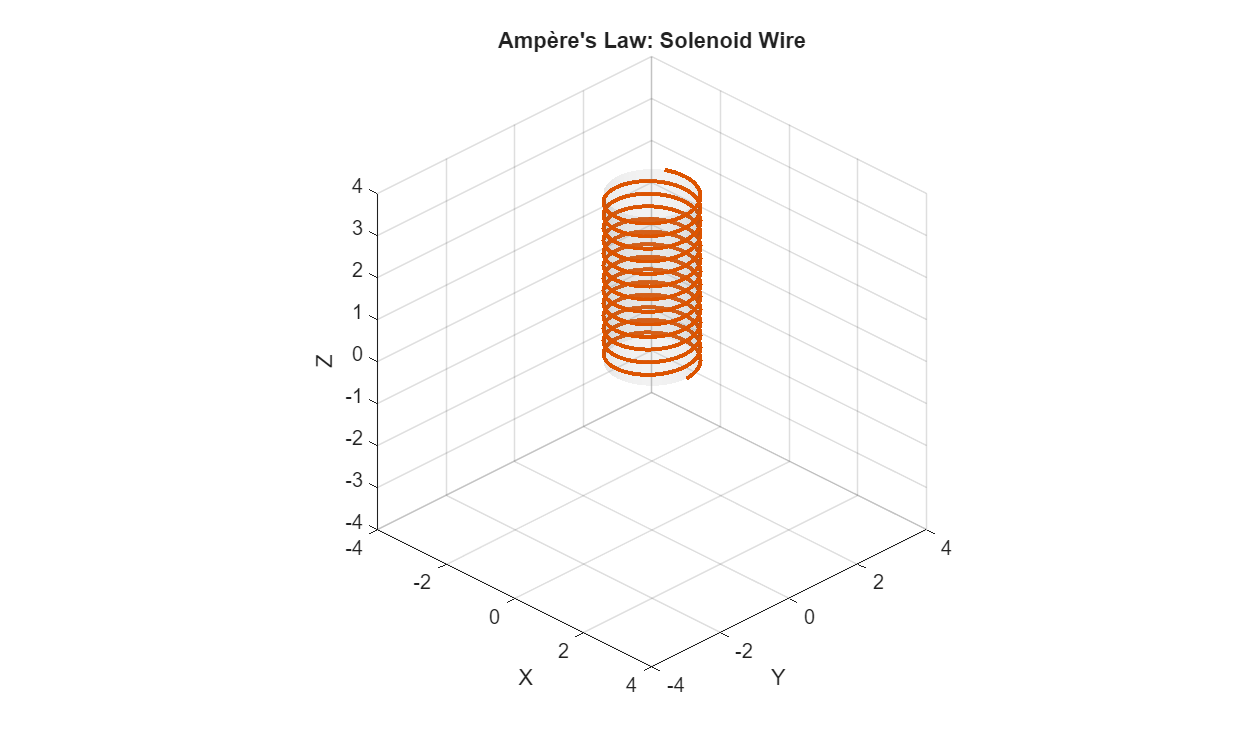

$$\mathrm{Which of the following Amperian loops is most appropriate for calculating the magnetic field inside a long solenoid using Ampère s Law?}$$

$$\mathrm{A) A circular loop centered on the axis of the solenoid and lying in the plane perpendicular to the solenoid}$$

$$\mathrm{B) A square loop lying entirely outside the solenoid}$$

$$\mathrm{C) A circular loop that wraps around the outside of the solenoid, following the windings}$$

$$\mathrm{D) A rectangular loop with one side inside the solenoid and one side outside, oriented parallel to the solenoid's axis}$$

AmpereExercises = GenerateAmpereProblem("Solenoid");

 

function y = GenerateAmpereProblem(Type)
arguments
 Type (1,1) string
end
    
    switch Type 
        case "Solenoid"
            y.Config = "Solenoid";
            Options = ["'A) A circular loop centered on the axis of the solenoid and lying in the plane perpendicular to the solenoid'";...
                "'B) A square loop lying entirely outside the solenoid'";...
                "'C) A circular loop that wraps around the outside of the solenoid, following the windings'";...
                "'D) A rectangular loop with one side inside the solenoid and one side outside, oriented parallel to the solenoid's axis'"];
            Question = "'Which of the following Amperian loops is most appropriate for calculating the magnetic field inside a long solenoid using Ampère s Law?'";
        case "Toroid"
            y.Config = "Toroid";
            Options = ["'A) A straight line passing through the center of the toroid'";...
                "'B) A circular loop centered on the axis of the toroid and lying in the plane of the windings'";...
                "'C) A circular loop lying perpendicular to the plane of the toroid'";...
                "'D) A square loop surrounding the entire toroid'"];
            Question = "'Which of the following Amperian loops is most appropriate for calculating the magnetic field inside a toroid using Ampère s Law?'";
        case "??"
            warning("Please, select either Toroid or Solenoid.")
            y = [];
            return
    end

    PlotAmpereExample(ConfigType=y.Config);
    displayFormula(Question)
    for i = 1:4
        displayFormula(Options(i))
    end
end

$$\mathrm{Correct. This loop takes advantage of the solenoid's symmetry and allows you to relate the field inside to the enclosed current.}$$

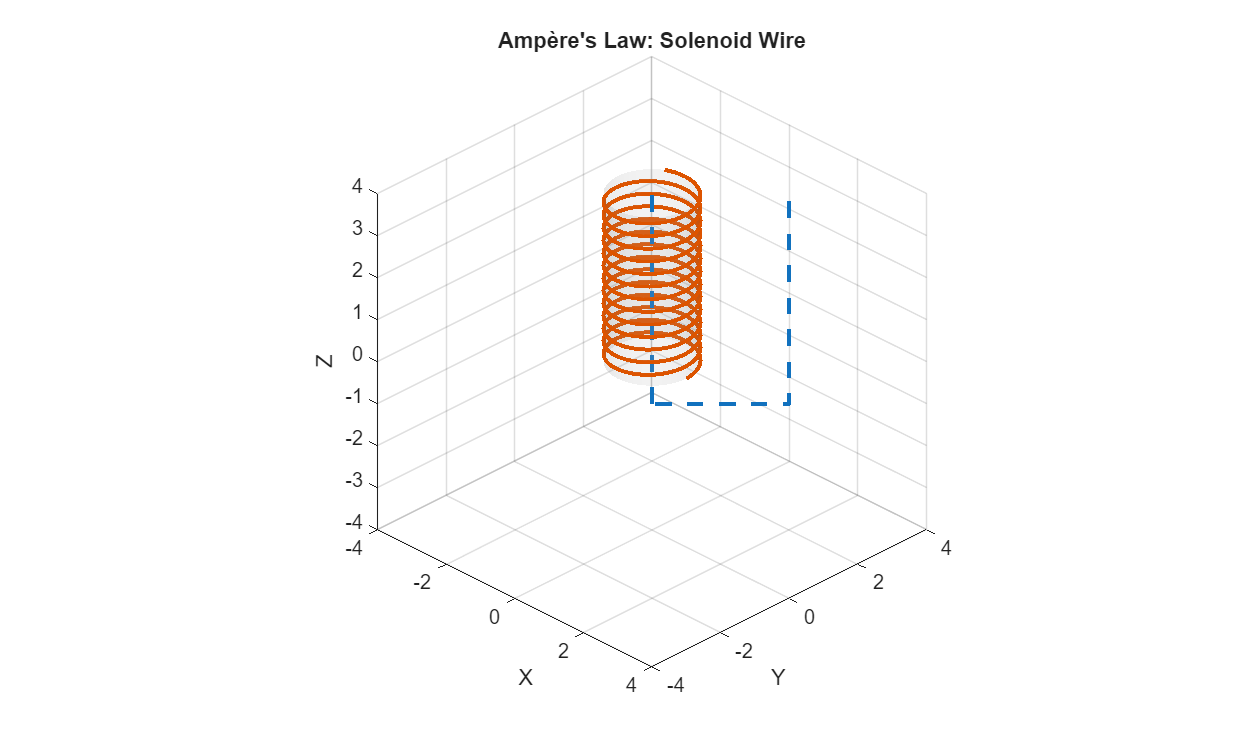

CheckExercise4(AmpereExercises,"D")


function CheckExercise4(Prob,Answer)
    if ~isfield(Prob,"Config")
        warning("Generate a problem above before to submit an answer.")
        return
    end
    switch Prob.Config
        case "Solenoid"
            switch Answer
                case "A"
                    displayFormula("'Incorrect. This loop is useful for wires, not for the solenoid's axial field.'")
                case "B"
                    displayFormula("'Incorrect. No current is enclosed, so Ampère's Law gives zero.'")
                case "C"
                    displayFormula("'Incorrect. This does not match the field's direction or symmetry.'")
                case "D"
                    displayFormula("'Correct. This loop takes advantage of the solenoid's symmetry and allows you to relate the field inside to the enclosed current.'")
                    PlotAmpereExample(ConfigType=Prob.Config,ShowAmperian=true);
            end
        case "Toroid"
            switch Answer
                case "A"
                    displayFormula("'Incorrect. A straight line does not exploit the symmetry of the toroid.'")
                case "B"
                    displayFormula("'Correct. This loop matches the symmetry and allows for easy application of Ampère's Law.'")
                    PlotAmpereExample(ConfigType=Prob.Config,ShowAmperian=true);
                case "C"
                    displayFormula("'Incorrect. The field is not constant or tangent along such a loop.'")
                case "D"
                    displayFormula("'Incorrect. A square loop does not match the symmetry and complicates the calculation.'")
            end
    end
end

Now that you have selected the correct Amperian line, you can count the current enclosed in the Amperian line

 **Exercise 5.** Determine the total current enclosed by the Amperian loop.

 
AmpereExercises = GenerateProblem5(AmpereExercises);

$$\mathrm{What would be the value of}I_{\mathrm{enclosed}}\mathrm{with:}$$

$$\mathrm{- Number of loop:}N=20$$

$$\mathrm{- Current:}\text{I}=7A$$

$$\mathrm{You can type your answer below in Ampere or directly using the symbol N and I for number of loops and current.}$$


function y = GenerateProblem5(Prob)
    if ~isfield(Prob,"Config")
        displayFormula('"Please generate a problem and complete exercise 4 before to attempt exercise 5."')
    end
    Prob.NumLoop = sym(randi([20 40]));
    Prob.Current = sym(randi([2 7]));
    displayFormula(["'What would be the value of '" "I_enclosed" "' with:'"])
    displayFormula(["'  - Number of loop: '" "N == Prob.NumLoop"])
    displayFormula(["'  - Current: '" "I == Prob.Current" "' A'"])
    displayFormula("' '")
    displayFormula("'You can type your answer below in Ampere or directly using the symbol N and I for number of loops and current.'")
    Prob.Current = separateUnits(Prob.Current);
    y = Prob;
end

CheckExercise5(AmpereExercises,"N*I")

$$\mathrm{Correct! You calculated the total count of current inside the Amperian line correctly.}$$

 

function CheckExercise5(Prob,Answer)
    if ~isfield(Prob,"Config")
        displayFormula('"Please generate a problem and complete exercise 4 before to attempt exercise 5."')
    end
    if ~isfield(Prob,"NumLoop")
        displayFormula('"Generate a problem above before to submit your answer."')
    end
    
    % Right Answer:
    N = Prob.NumLoop;
    I = Prob.Current;
    RightAnswer = double(N*I);
    Case1 = double(I);
    if Answer ~= ""
        Answer = double(eval(Answer));
    else
         displayFormula('"Please add your answer in the edit field above."')
        return
    end

    % Feedback
    if IsClose(Answer,RightAnswer)
        displayFormula('"Correct! You calculated the total count of current inside the Amperian line correctly."')
    elseif IsClose(Answer,Case1)
        displayFormula('"Incorrect, you accounted for only one of the current through the Amperian line, but there is many winding, so how many current total?"')
    else
        displayFormula('"Incorrect, please try again. Ask yourself how many time does the wire goes inside the Amperian line?"')
    end
    
end

The next step is to calculate the integral $\oint \vec{B} \cdot d\vec{l}$.

If you need to learn more about line integral, you should consider reviewing our line integral script in the multivariable integral module [here](https://github.com/MathWorks-Teaching-Resources/Multivariable-Integrals/blob/release/Scripts/LineIntegrals.m).

 **Exercise 6.** Enter your answer the the edit field below.

Use only the symbolic variables **B**, **L**, **R, **and constants like **pi** when entering your expression for the magnetic field.

 
switch AmpereExercises.Config
    case "Toroid"
        displayFormula("'- The Amperian line radius is (R)'")
    case "Solenoid"
        displayFormula("'- Consider the solenoid length to be (L) and approximate the field to be constant along the central segment and null everywhere else.'")
end

$$\mathrm{- Consider the solenoid length to be (L) and approximate the field to be constant along the central segment and null everywhere else.}$$

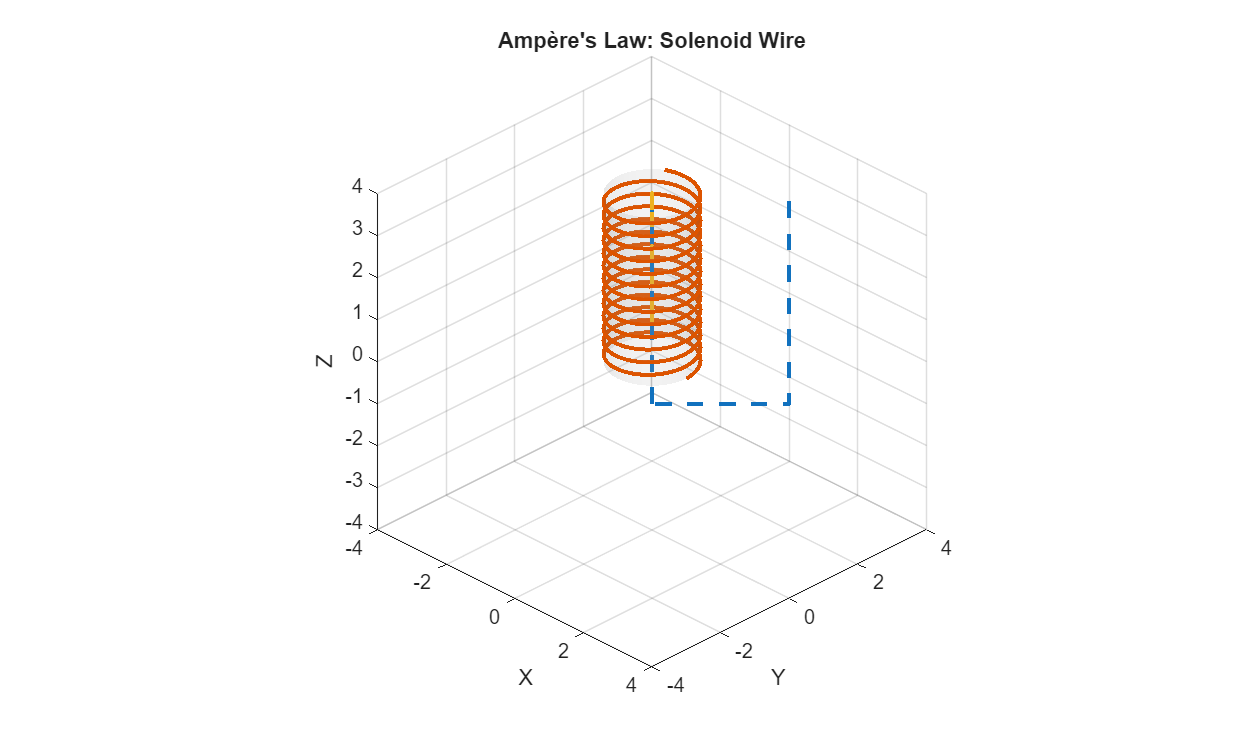

 PlotAmpereExample(ConfigType=AmpereExercises.Config,ShowAmperian=true,ShowB=true);

CheckExercise6(AmpereExercises,"B*L")
 

$$\mathrm{Correct! You have computed the integral correctly.}$$


function CheckExercise6(Prob,Answer)

    if Answer ~= ""
        Answer = str2sym(Answer);
    else
         displayFormula('"Please add your answer in the edit field above."')
        return
    end
    if ~isfield(Prob,"Config")
        displayFormula('"Please generate a problem and complete exercise 4 before to attempt exercise 6."')
    end
    
    % Right Answer:
    syms B L R
    switch Prob.Config
        case "Toroid"
            RightAnswer = 2*pi*B*R;
        case "Solenoid"
            RightAnswer = B*L;
    end

    % Feedback
    if isequal(Answer,RightAnswer)
        displayFormula('"Correct! You have computed the integral correctly."')
    else
        displayFormula('"Incorrect, remember that in your case the field can be considered constant along the integration line."')
    end
    
end

Congratulations if you made it this far! You have correctly calculated the right hand side and left hand side of:


$$\oint \vec{B} \cdot d\vec{l} = \mu_0 I_{\text{enclosed}} \qquad (5)$$


The last step to express the field in your configuration is to rearrange the equation.

 **Exercise 7.** Rearrange the solution and enter the expression for the magnetic field below:

Use only the symbolic variables **B**, **L**, **R**, **mu0**, **N**, and **I** (and constants like **pi**) when entering your expression for the magnetic field.

CheckExercise7(AmpereExercises,"mu0*N*I/L")

$$\mathrm{Correct! You have evaluated the integral properly.}$$

 


function CheckExercise7(Prob,Answer)

    if Answer ~= ""
        Answer = str2sym(Answer);
    else
        displayFormula('"Please enter your expression for the magnetic field in the field above."')
        return
    end

    if ~isfield(Prob,"Config")
        displayFormula('"Please generate a problem and complete Exercise 4 before attempting Exercise 7."')
        return
    end
    
    % Right Answer:
    syms B L R mu0 N I 
    switch Prob.Config
        case "Toroid"
            RightAnswer = mu0 * N * I / (2*pi*R);
        case "Solenoid"
            RightAnswer = mu0 * N * I / L;
    end

    % Feedback
    if isequal(Answer,RightAnswer)
        displayFormula('"Correct! You have evaluated the integral properly."')
    else
        displayFormula('"Incorrect. Remember that the enclosed current is I_{enclosed} = N * I."')
    end
    
end

 **Reflect.** Notice how Ampère's law provides exact solutions when symmetry allows us to evaluate the line integral easily. This is analogous to how Gauss's law simplifies electric field calculations for symmetric charge distributions.

This activity demonstrated  that, for both the toroid and the solenoid, increasing the number of loops strengthens the magnetic field even when the current remains unchanged. There is a proportional relationship between the field and the enclosed current $I_\text{enclosed}=NI$.

## Conclusion

We have seen how magnetic fields originate from electric currents and how they influence moving charges without doing work. From the Lorentz force to the Biot–Savart and Ampère’s laws, these principles give us powerful tools to analyze and visualize magnetic phenomena. Mastering these concepts is essential for understanding electromagnetism and its applications in modern technology.

function tf = IsClose(A,B)
    lhs = abs(A-B);
    rhs = max(1e-4,1e-4*max(abs(A),abs(B)));
    tf = lhs <= rhs;
end

[⇦ Main Menu](matlab:open('MainMenu.mlx'))